# Blending

Goal: blend the edges and the recolorized image into one output drawing image

Method: 

clear all;
close all;

## 0) Import the data

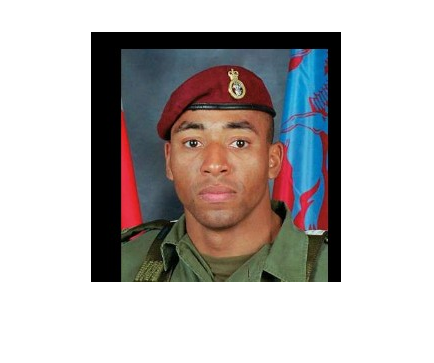

% import the data
%im = im2double(imread('../lfw/Avril_Lavigne_0001.jpg'));
%im = im2double(imread('../lfw/Ai_Sugiyama_0002.jpg'));
im = im2double(imread('../lfw/Ainsworth_Dyer_0001.jpg'));
%im = im2double(imread('../lfw/Alejandro_Toledo_0003.jpg'));
%im = im2double(imread('../lfw/Allyson_Felix_0003.jpg'));
imshow(im)


% grayscale version
im_g = rgb2gray(im);
%imshow(im_g)

% BW version: from locally adaptive Otsu's thresholding
im_bw = imbinarize(im_g);
%imshow(im_bw)

## Blending

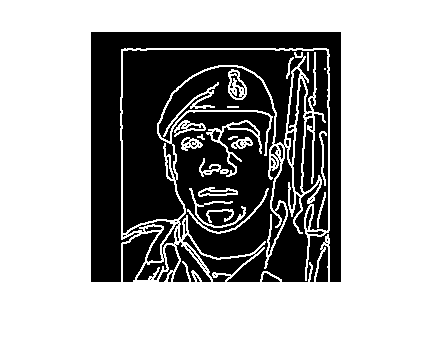

% hyperparameters
thresh = 0.2; % threshold for edge detection
k = 2; % size of dilatation structuring element
n_cluster = 4; % number of output colors
gamma = 0.5; % color adjustement
isLAB = true; % space in which to perform the clustering

level = 0.3; % color of edges
sigma_color = 0.1; % std for color smoothering
amplitude = 1; % importance of color gradient
sigma_g = 5; % std for color gradient

% edges
edges_d = edge_extractor(im, thresh, k);
imshow(edges_d)

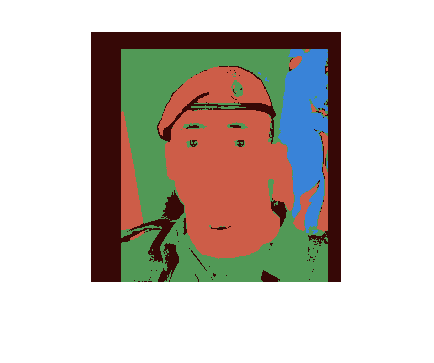


% recolorized image
im_color = cluster_color(im, n_cluster, gamma, isLAB);
imshow(im_color)

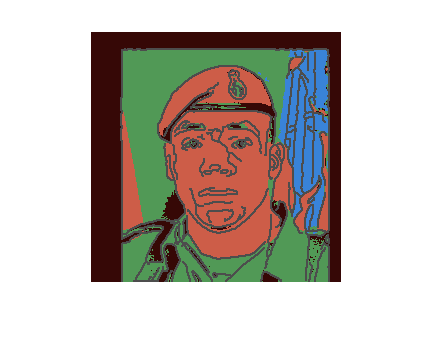


% add edges in black on image
im_edge = im_color .* (1-edges_d)  + level*edges_d;
imshow(im_edge)

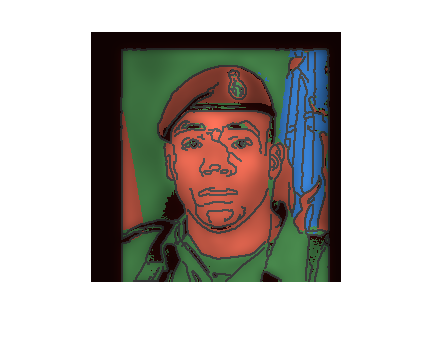


% use smoothered grayscale for color gradient effect
color_gradient =  amplitude * imgaussfilt(im_g, sigma_g); 
% center in 0.5
color_gradient = color_gradient + (0.5 - mean(color_gradient(:)));

% apply the color gradient information
im_gc = imgaussfilt(im_edge, sigma_color) .* color_gradient;
im_gc = im_gc / max(im_gc(:));
imshow(im_gc)


% smooth more along edges
% don't smooth on boundary foreground / background
